# Изучение красного смещения звёзд

close all
clear variables

#### 1. Импорт данных

spectra     = importdata("spectra.csv")

spectra = 	1.0e+-12 *

    0.3088    0.1340    0.0598    0.0892    0.1088    0.1625    0.0392
    0.3136    0.1338    0.0607    0.0898    0.1084    0.1630    0.0382
    0.3105    0.1347    0.0618    0.0915    0.1104    0.1615    0.0371
    0.3076    0.1357    0.0625    0.0931    0.1124    0.1586    0.0378
    0.3088    0.1354    0.0627    0.0936    0.1122    0.1574    0.0391
    0.3105    0.1343    0.0622    0.0932    0.1136    0.1589    0.0396
    0.3122    0.1335    0.0619    0.0929    0.1138    0.1611    0.0402
    0.3101    0.1325    0.0620    0.0925    0.1130    0.1607    0.0399
    0.3078    0.1335    0.0626    0.0924    0.1124    0.1593    0.0387
    0.3047    0.1329    0.0625    0.0918    0.1108    0.1582    0.0379


starNames   = importdata("star_names.csv");
lambdaStart = importdata("lambda_start.csv");
lambdaDelta = importdata("lambda_delta.csv");

#### Требуемые константы

lambdaPr     = 656.28;     % nm
speedOfLight = 299792.458; % km\c

#### 2. Определение числа наблюдений и количества звёзд

[numObserv, numStars] = size(spectra);

#### 3. Получение вектора длины волн lambda

lambdaEnd = lambdaStart + (numObserv - 1) * lambdaDelta;
lambda    = (lambdaStart : lambdaDelta : lambdaEnd)';

#### 4. Получение векторов минимальных интенсивностей и их индексов

[spectraStars, indx] = min(spectra);
lambdaStars = lambda(indx);

#### 5. Рассчет скорости движения всех звезд (вектор  speed)

z     = (lambdaStars / lambdaPr) - 1;
speed =  z * speedOfLight;

#### 6. Построение графика спектров всех звёзд

graphStars = figure;

hold on;
for indxGraph = 1 : numStars
    if speed(indxGraph) > 0
        plot(lambda, spectra(:, indxGraph), ...
             '-', ...
             'Linewidth', 3);
    else 
        plot(lambda, spectra(:, indxGraph), ...
             '--', ...
             'Linewidth', 1); 
    end
end
hold off;

#### 7. Добавление на график названия, подписи осей, сетки и легенды

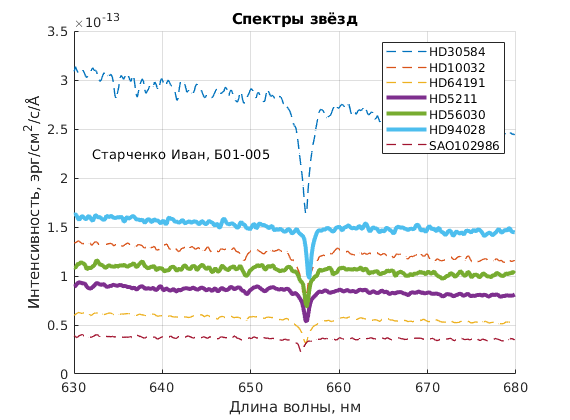

set   (graphStars, 'Visible', 'on'); 
xlabel('Длина волны, нм');
ylabel(['Интенсивность, эрг/см^2/с/', char(197)]);
title ('Спектры звёзд');
text(632, 2.25 * 10^(-13),'Старченко Иван, Б01-005');
legend(starNames);
grid on;

#### 8. Получение вектора **movaway**

movaway = starNames(speed > 0);

#### 9. Сохранение графика как картини в формате png

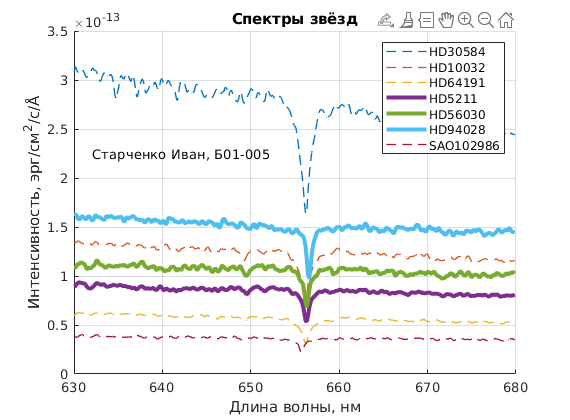

saveas(graphStars, 'spectra.png');